%% TRABAJO FINAL CÁLCULO EN UNA VARIABLE
%% CRISTIAN ALVEAR, HERMAN ESPINOSA, ARANZA MOREIRA
%% 31 DE ENERO DEL 2026
%% TEMA: Gini educativo en ecuador, comparación 2010 con 2000


% 1. Cargar la base de datos
opts = detectImportOptions('BL2013_MF1599_v2.2.csv');
data = readtable('BL2013_MF1599_v2.2.csv', opts);

% 2. Filtrar datos (Ecuador, Año 2010)
data_ec = data(strcmp(data.country, 'Ecuador') & data.year == 2010, :);

% 3. Extraer puntos originales (Los 7 niveles educativos)
p_orig = [data_ec.lu, (data_ec.lp-data_ec.lpc), data_ec.lpc, ...
          (data_ec.ls-data_ec.lsc), data_ec.lsc, ...
          (data_ec.lh-data_ec.lhc), data_ec.lhc] / 100;
x_niveles = [0, 3, 6, 9, 12, 14, 16];

%% CURVA DE LORENZ
P_curva = [0, cumsum(p_orig)]; 
H_curva = [0, cumsum(p_orig .* x_niveles) / sum(p_orig .* x_niveles)];

%% SUAVIZACIÓN DE LA CURVA DE LORENZ
% Cambia este número para ver cómo cambia la precisión (ej. 5, 20, 100, 1000)
n_rectangulos = 999; 

% Crear el eje X con las subdivisiones solicitadas
ejeX_riemann = linspace(0, 1, n_rectangulos + 1);
ancho_dx = 1 / n_rectangulos;

% Interpolar para obtener las alturas en cada subdivisión
% Usamos 'pchip' para mantener la forma real de la curva de Lorenz
ejeY_riemann = interp1(P_curva, H_curva, ejeX_riemann, 'pchip');

%% CÁLCULO DE LA SUMA DE RIEMANN (IZQUIERDA)
area_B = 0;
for i = 1:n_rectangulos
    % Altura tomada del punto izquierdo del intervalo
    altura = ejeY_riemann(i); 
    area_B = area_B + (ancho_dx * altura);
end

% Cálculo del Coeficiente de Gini
gini_final = 1 - 2 * area_B;

%% VISUALIZACIÓN
clf; % Limpiar figura actual
hold on;

% Dibujar los rectángulos de Riemann
for i = 1:n_rectangulos
    % Coordenadas del rectángulo: [x_inicio, y_inicio, ancho, altura]
    rectangle('Position', [ejeX_riemann(i), 0, ancho_dx, ejeY_riemann(i)], ...
              'FaceColor', [0.8 0.9 1], 'EdgeColor', [0.4 0.4 0.4]);
end

% Dibujar la Curva de Lorenz original (para comparar)
plot(P_curva, H_curva, 'r-o', 'LineWidth', 1.5, 'DisplayName', 'Puntos Originales');
% Dibujar la línea de igualdad
plot([0 1], [0 1], 'k--', 'LineWidth', 1, 'DisplayName', 'Igualdad Perfecta');

title(['Suma de Riemann (Izquierda) con n = ', num2str(n_rectangulos)]);
xlabel('Población Acumulada');
ylabel('Educación Acumulada');
legend('Rectángulos (Suma Izq)', 'Curva Real', 'Igualdad', 'Location', 'NorthWest');

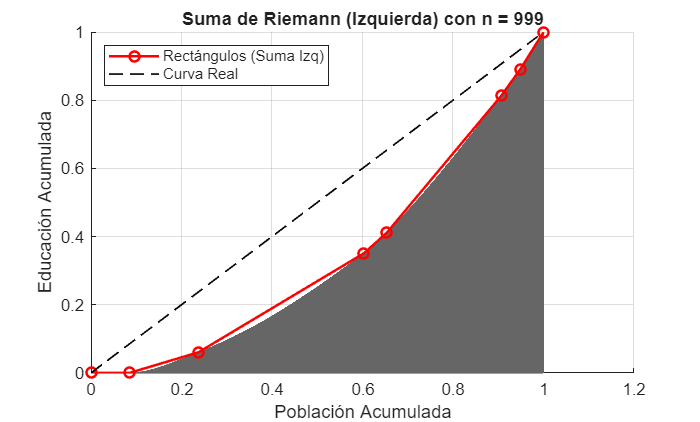

grid on;


% Mostrar resultados en consola
fprintf('--- Resultados con n = %d ---\n', n_rectangulos);

--- Resultados con n = 999 ---


fprintf('Área bajo la curva (B): %.4f\n', area_B);

Área bajo la curva (B): 0.3288


fprintf('Coeficiente de Gini: %.4f\n', gini_final);

Coeficiente de Gini: 0.3423
